# Clase 03_b >> Estructuras y sistemas

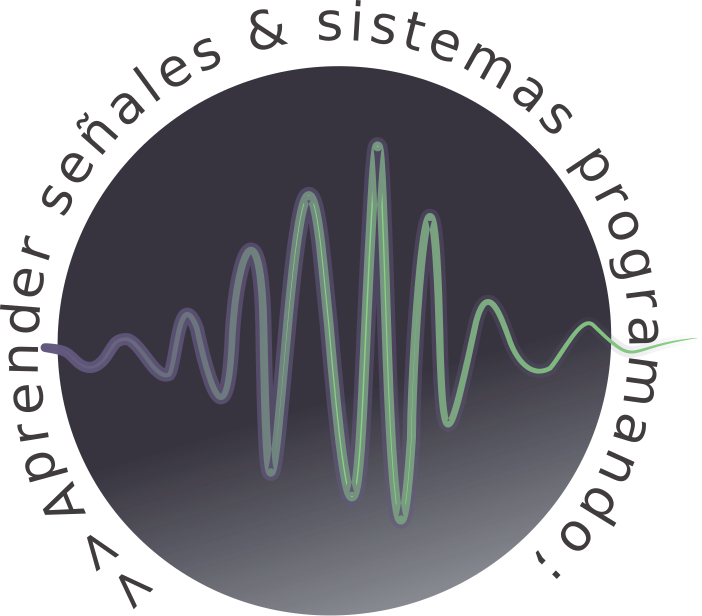

# Funciones (II)

Tratar las funciones en MATLAB sólo desde el punto de vista de un archivo auxiliar es un tremendo error. La escritura y manipulación de funciones es la mayor potencia (probablemente la única) del lenguaje. Este planteamiento choca con la formulación básica de la función y se acerca más a los lenguajes orientados a objetos donde podemos asignar un método a una variable [I Nogueras GB, 2007]. Ya hemos hablado del comando help y cómo debe utilizarse. Nosotros también podemos dotar nuestras funciones de una ayuda parecida de una manera muy fácil. Todas las líneas comentadas entre la sentencia **function** y la primera sentencia ejecutable nos saldrán por pantalla si llamamos a la función mediante el comando **help**, a esto se lo denomina **docstring.**

## Control en los argumentos 

help varargin

varargin - Variable-length input argument list

    This MATLAB function is an input variable in a function definition statement
    that enables the function to accept any number of input arguments.

    varargin

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/nargin.html">nargin</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/narginchk.html">narginchk</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/varargout.html">varargout</a>

    Reference page for varargin



help nargin

nargin - Number of function input arguments

    This MATLAB function returns the number of function input arguments given in the
    call to the currently executing function.

    nargin
    nargin(fun)

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/narginchk.html">narginchk</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/nargout.html">nargout</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/varargin.html">varargin</a>

    Reference page for nargin
    Other functions named nargin



Ejemplo:

ejemplo_1(1,2,3,4,1)

Total de argumentos de entrada = 5
Entradas en varargin: 3
   3
   4
   1


De igual manera sucede con los argumentos de salida:

help varargout

varargout - Variable-length output argument list

    This MATLAB function is an output variable in a function definition statement
    that enables the function to return any number of output arguments.

    varargout

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/nargout.html">nargout</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/nargoutchk.html">nargoutchk</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/varargin.html">varargin</a>

    Reference page for varargout



help nargout

nargout - Number of function output arguments

    This MATLAB function returns the number of function output arguments specified
    in the call to the currently executing function.

    nargout
    nargout(fun)

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/nargoutchk.html">nargoutchk</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/varargout.html">varargout</a>

    Reference page for nargout
    Other functions named nargout



La utilidad de controlar los argumentos de entrada y salida, radica en poder tener mayor control de la función y los posibles errores en su uso. A continuación se presenta un ejemplo utilizando **docstring**, **varargin**, **error:**

help promedio

  avg = promedio(v) :: v es un vector
 
  Calcula la media de los elementos de un vector 



promedio([60 60 60])

ans = 60

promedio(10)

ans = 10

% Probando los errores
%promedio(60,12)
%promedio('vector')

## Inline

Si quisieramos evaluar una función con alguna expresión particular, el camino mas sencillo es utilizar **inline, **como se observa a continuación:

prom_pon = inline('promedio(x)*0.3 + promedio(y)*0.7','x','y'); % Ej: promedio ponderado de dos evaluaciones
alumnos = [3,5,2,8];
alumnos_prom = prom_pon (alumnos(1,1:2), alumnos(1,3:4))

alumnos_prom = 4.7000

Esta práctica es muy frecuente y útil, pensemos que por cada vez que utilicemos un inline nos ahorramos un archivo [I Nogueras GB, 2007].

# Funciones anónimas

Una **función anónima **es una forma simple de la función de MATLAB que se define dentro de una sola instrucción de MATLAB. Está formada por una sola expresión y con cualquier cantidad de argumentos de entrada y salida. Es posible definir una función anónima en la línea de comandos de MATLAB o dentro de una función o script. Esta alternativa ofrece un rápido medio para crear funciones simples sin tener que volver a crear un archivo nuevo para ellas cada vez.

La sintaxis para la creación de una función anónima a partir de una expresión es:


$$\text{f= @(listaArgumentos)expresion}$$


La siguiente instrucción crea una función anónima que busca el cuadrado del seno de un número. Cuando se llama esta función, MATLAB asigna el valor del argumento de entrada a la variable `x`, y luego usa `x` en la ecuación:

varsin = @(x) sin(x)^2;
varsin (2*pi)

ans = 5.9990e-32

**Las funciones anónimas son conocidas en otros lenguajes como función lambda.**

## Señales discretas básicas

Veamos algunos ejemplos de como aprovechar el uso de **funciones anónimas**, en la declaración de señales discretas. Por ejemplo en la definición de un **pulso unitario**:


$$P[n]=\begin{cases} 1/\tau, \text{para } \vert n \vert< \tau/2  \\  0, \text{resto  } 
\end{cases}$$
 
$$=\left\lbrace \ldotp \ldotp \ldotp ,0,1,1^{\uparrow } ,1,0,\ldotp \ldotp \ldotp \right\rbrace$$


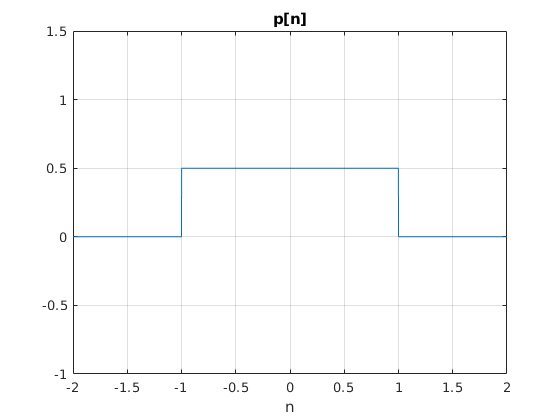

p = @(n,T) 1/T*(abs(n)<T/2);
n=-2:0.001:2;

plot(n,p(n,2));xlabel('n'); title('p[n]'); ylim([min(p(n,2))-1,max(p(n,2))+1]); grid on

Un uso muy interesante de las **funciones anónimas** es la creación de estructuras de datos con funciones. Como ejemplo crearemos unas celdas donde los elementos sean las funciones trigonométricas básicas:

trifun = {@sin,@cos,@tan}

trifun = 1×3 cell array
    {@sin}    {@cos}    {@tan}


trifun{3}(pi/2)

ans = 1.6331e+16

**Gracias a las funciones anónimas podemos asignar funciones a variables esto nos servirá para pasar funciones como argumentos**. Si lo pensamos un poco nos daremos cuenta que no es nada fácil llamar a una función cuyo nombre no conocemos y sin saber en qué directorio se encuentra. La solución a este problema son las funciones handles, por eso se recomienda encarecidamente su uso.

# Funciones principales y subfunciones

Cualquier función que no sea anónima debe definirse dentro de un archivo. Cada archivo de función contiene una *función principal* que aparece primero, y cualquier número de *subfunciones* que pueden seguir a la principal. Las funciones principales tienen un  alcance más amplio que las subfunciones. Es decir, las funciones  principales pueden ser llamadas desde el exterior del archivo que las  define (por ejemplo, desde la línea de comandos de MATLAB o desde  funciones en otros archivos), mientras que las subfunciones no. Las  subfunciones solo son visibles para la función principal y otras  subfunciones dentro de su propio archivo.

Un archivo de funcion en MATLAB permite contener código para más de una función. En estos archivos la primera función en el archivo se llama **función principal.** Esta función es visible para las funciones en otros archivos, o puede ser llamada desde linea de comandos. Funciones adicionales dentro del archivos se las denomina **funciones locales **y pueden ocurrir en cualquier orden despues de la función principal. Las funciones locales sólo son accesibles desde el mismo archivo. **Son equivalentes a las subrutinas en otros lenguajes de programación.**

help descriptores

  [avg, med] = descriptores(x) :: x es un vector de números
 
  Función para calcular la media (avg) y la mediana (med)



[media, mediana] = descriptores([10 20 22 43 45 67 90 12])

media = 38.6250

mediana = 32.5000

## Llamar funciones locales usando handles

Todo lo visto hasta ahora fue para poder aplicar estas estructuras sumamente imporatnes para un codigo legible, prolijo y funcional. Vamos a ver un ejemplo, donde la funcion permite obtener caracteristicas de una elipse:

help elipseElementos

  eli = elipseElementos :: sin argumento de entrada
 
  Función para determinar caracteristicas de una elipse.
  
  Argumentos =  a: semieje mayor ; b: semieje menor
 
  .foco :: arg (a,b) -- (foco de la elipse) -- 
  .excentricidadb :: arg (a,b) -- (excentricidad de la elipse) --
  .area :: arg (a,b) -- (area de la elipse) --
 
  Septiembre 2017



h = elipseElementos

h = struct with fields:
             foco: @calculoFoco
    excentricidad: @calculoExcentricidad
             area: @calculoArea


h.foco(3,1)

ans = 2.8284

h.area(3,1)

ans = 9.4248

h.excentricidad(3,1)

ans = 0.9428

**Importante**: entender esta estructura permite avanzar hacia una programaccion orientada a objetos.

# Funciones anidadas

Los lenguajes de programación modernos permiten las funciones recursivas. Una función recursiva es aquella que se invoca a sí misma. Existen problemas que por su naturaleza recurrente se solucionan de una forma elegante mediante una función recursiva. 

Un ejemplo clásico es el cálculo del factorial de un número entero no negativo $n$ (se define como el producto de todos los enteros positivos menores o iguales que $n$). Por ejemplo, $4!=4*3*2*1=24$. El $0!=1$. En MATLAB el factorial del número $n$ se puede calcular trivialmente como :

clear n ans
n = 100;

tic
prod(1:n)

ans = 9.3326e+157

toc

Elapsed time is 0.019997 seconds.


o utilizando:

tic
factorial(n)

ans = 9.3326e+157

toc

Elapsed time is 0.085935 seconds.


El factorial de un número tambien se puede definir de una manera recurrente:


$$n!=\begin{cases} 1 \text{ si } n=0 \\  n*(n-1) \text{ si  } n>0\end{cases}$$


tic
fact(n)

ans = 9.3326e+157

toc

Elapsed time is 0.025384 seconds.


Todo algoritmo recursivo se puede resolver mediante un algoritmo iterativo, a veces apoyándose en una estructura de datos de tipo cola o de tipo pila. **En la mayoría de los lenguajes de programación la solución iterativa es mas eficiente que la recursiva, pues evita la sobrecarga asociada a una llamada a función**. Sin embargo, para muchos problemas la solución recursiva es mas elegante y fácil de comprender, por lo que se prefiere la solución recursiva pese a su menor eficiencia.

# Encapsulado de funciones

El encapsulado de funciones tiene dos utilidades principales:

- **Encapsular** partes del cálculo en una funcion principal dentro de una funcion secundaria.

- Posibilitar que argumentos de salida sean funciones mediante funciones **anónimas**.

El primer uso es trivial, no es más que agrupar una tarea repetitiva para no tener que escribirla varias veces. El segundo uso es una de las sutilezas proporcionadas por las funciones anónimas. Como podemos definir subfunciones (o subrutinas) siempre que no influyan en la funcion principal nada nos impide asignarlas a un a función handle que se pasará en la salida como argumento. Es exactamente el mismo concepto que el de utilizar funciones como argumentos de funciones pero a la inversa. Por ejemplo, supongamos que estamos diseñando un filtro para una señal, un filtro pasa-bajos según una determinada frecuencia ω . Lo más sencillo sería hacer una función pasa-bajos que recibiera tres argumentos, el espectro en frecuencias, la longitud del espectro y la frecuencia de corte. Una solución mucho más elegante puede ser definir una función de construcción que devuelve un function handle con un filtro que utilizamos como otra función por separado. De este modo conseguiríamos reducir toda una colección de filtros a una única función generadora. 

# Ejercicio propuesto (Script 11)

%open discSignal_Diagram.pdf

Se propone desarrollar una funcion denominada **discSignal,** la cual cuenta con una funcion constructora que llama a las funciones locales usando funciones anónimas. Utilizando como ejemplo la funcion `elipseElementos,` crear 4 funciones locales:

- Una función que genera una secuencia de señal impulso.

- Una función que genera una secuencia de señal escalon.

- Una función que genera una secuencia de señal rampa.

- Una función para plot de una secuencia dada.

En todos los casos los argumentos de entrada son:

- n0 = indice de la ubicación del valor 0.

- n1 = inicio del intervalo.

- n2 = final del intervalo.

En todos los casos los argumentos de salida son:

- x = secuencia de los valores de la señal deseada.

- n = secuencia de los indices.

Utilizar la estructura** try**, **catch**, para controlar errores.

help dicSignal

  eli = elipseElementos :: sin argumento de entrada
 
  Función para determinar caracteristicas de una elipse.
  
  Argumentos =  n0: indice de la ubicación del valor 0 ; n1: inicio del intervalo; n2: final del intervalo
 
  .imp :: argIn (n0,n1,n2) ; arOut(x,n) -- (señal impulso) -- 
  .esc :: argIn (n0,n1,n2) ; arOut(x,n) -- (sñal escalon) --
  .ramp:: argIn (n0,n1,n2) ; arOut(x,n) -- (señal rampa) --
 
  Scrip 11 - Septiembre 2017



sig = dicSignal

sig = struct with fields:
      imp: @impulso
      esc: @escalon
    rampa: @rampa
     plot: @plot


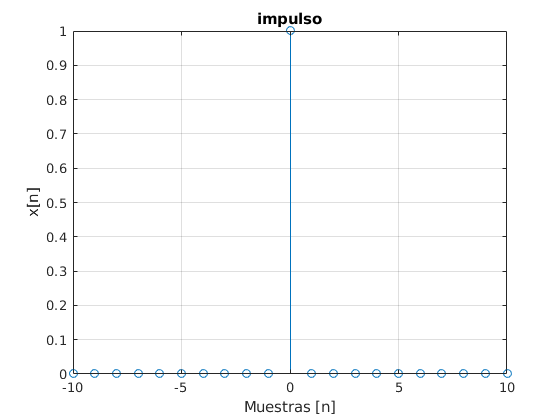

[x,n] = sig.imp(0,-10,10); sig.plot(x, n,'impulso')

**Consejo:**

- Es importante en este punto del aprendizaje usar los diagrams de flujo, como herramienta de diagramación y proyección ([https://www.draw.io](#null)).

# Referencias

- I Nogueras GB. **Introducción informal a Matlab y Octave**. 2007.